# Heat Equation using Finite Difference Method

## 
$$u_{i,j+1} =a\cdot u_{i+1,\;j} +\left(1-2a\right)u_{i,j} +a\cdot u_{i-1,j}$$


clear all;

% params
f = @(x) x .* (4-x);

c_sq = 1/2;

h = 1;
k = 1;

tn = 3;
xn = 4;

% function

x = 0:h:xn;
t = 0:k:tn;

% a = k * c_sq / h^2;
a = 0.5;

u = zeros(length(x), length(t));
u(:, 1) = f(x);

for j = 1:length(t)-1
    for i = 2:length(x)-1
        u(i, j+1) = a * u(i+1, j) + (1-2*a) * u(i, j) + a * u(i-1, j);
    end
end

for j = 1:length(t)
    for i = 1:length(x)
        fprintf('value at u(%d, %d) is %f\n', i-1, j-1, u(i, j));
    end
    fprintf('\n');
end

value at u(0, 0) is 0.000000
value at u(1, 0) is 3.000000
value at u(2, 0) is 4.000000
value at u(3, 0) is 3.000000
value at u(4, 0) is 0.000000


value at u(0, 1) is 0.000000
value at u(1, 1) is 2.000000
value at u(2, 1) is 3.000000
value at u(3, 1) is 2.000000
value at u(4, 1) is 0.000000


value at u(0, 2) is 0.000000
value at u(1, 2) is 1.500000
value at u(2, 2) is 2.000000
value at u(3, 2) is 1.500000
value at u(4, 2) is 0.000000


value at u(0, 3) is 0.000000
value at u(1, 3) is 1.000000
value at u(2, 3) is 1.500000
value at u(3, 3) is 1.000000
value at u(4, 3) is 0.000000


disp(u)

                   0                   0                   0                   0
   3.000000000000000   2.000000000000000   1.500000000000000   1.000000000000000
   4.000000000000000   3.000000000000000   2.000000000000000   1.500000000000000
   3.000000000000000   2.000000000000000   1.500000000000000   1.000000000000000
                   0                   0                   0                   0



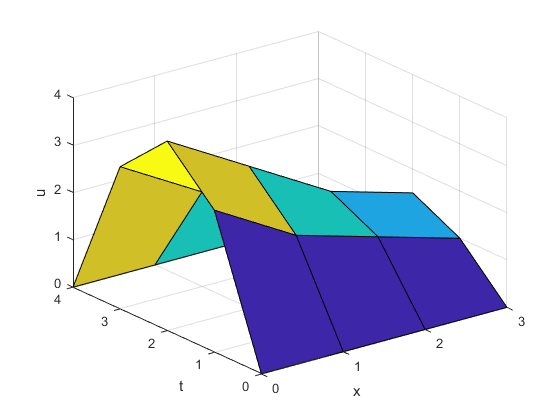

surf(t, x, u);
xlabel('x');
ylabel('t');
zlabel('u');

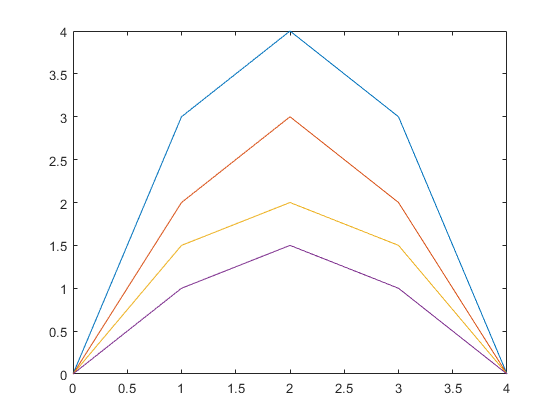

for j = 1:length(t)
    plot(x, u(:, j));
    hold on;
end
hold off;

clear all;

% params
f = @(x) sin(2*pi*x);

c_sq = 1/2;

h = 0.1;
k = 0.01;

tn = 0.02;
xn = 0.5;

% function

x = 0:h:xn;
t = 0:k:tn;

a = k * c_sq / h^2;
% a = 0.5;

u = zeros(length(x), length(t));
u(:, 1) = f(x);

for j = 1:length(t)-1
    for i = 2:length(x)-1
        u(i, j+1) = a * u(i+1, j) + (1-2*a) * u(i, j) + a * u(i-1, j);
    end
end

for j = 1:length(t)
    for i = 1:length(x)
        fprintf('value at u(%d, %d) is %f\n', i-1, j-1, u(i, j));
    end
    fprintf('\n');
end

value at u(0, 0) is 0.000000
value at u(1, 0) is 0.587785
value at u(2, 0) is 0.951057
value at u(3, 0) is 0.951057
value at u(4, 0) is 0.587785
value at u(5, 0) is 0.000000


value at u(0, 1) is 0.000000
value at u(1, 1) is 0.475528
value at u(2, 1) is 0.769421
value at u(3, 1) is 0.769421
value at u(4, 1) is 0.475528
value at u(5, 1) is 0.000000


value at u(0, 2) is 0.000000
value at u(1, 2) is 0.384710
value at u(2, 2) is 0.622475
value at u(3, 2) is 0.622475
value at u(4, 2) is 0.384710
value at u(5, 2) is 0.000000


disp(u)

                   0                   0                   0
   0.587785252292473   0.475528258147577   0.384710442146907
   0.951056516295154   0.769420884293814   0.622474571220695
   0.951056516295154   0.769420884293814   0.622474571220695
   0.587785252292473   0.475528258147577   0.384710442146907
   0.000000000000000                   0                   0



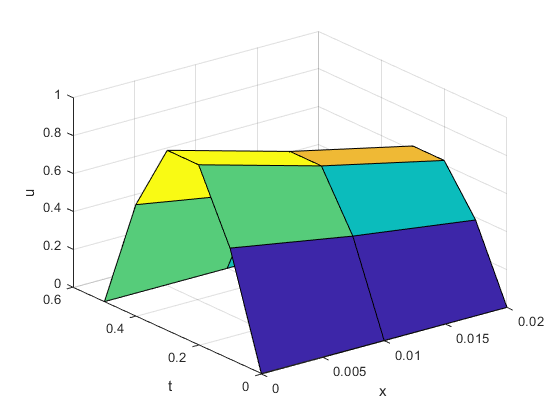

surf(t, x, u);
xlabel('x');
ylabel('t');
zlabel('u');

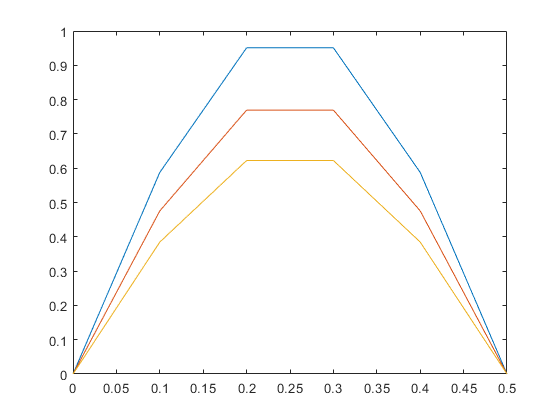

for j = 1:length(t)
    plot(x, u(:, j));
    hold on;
end
hold off;